## 1.1 Define the path and plot the original signal

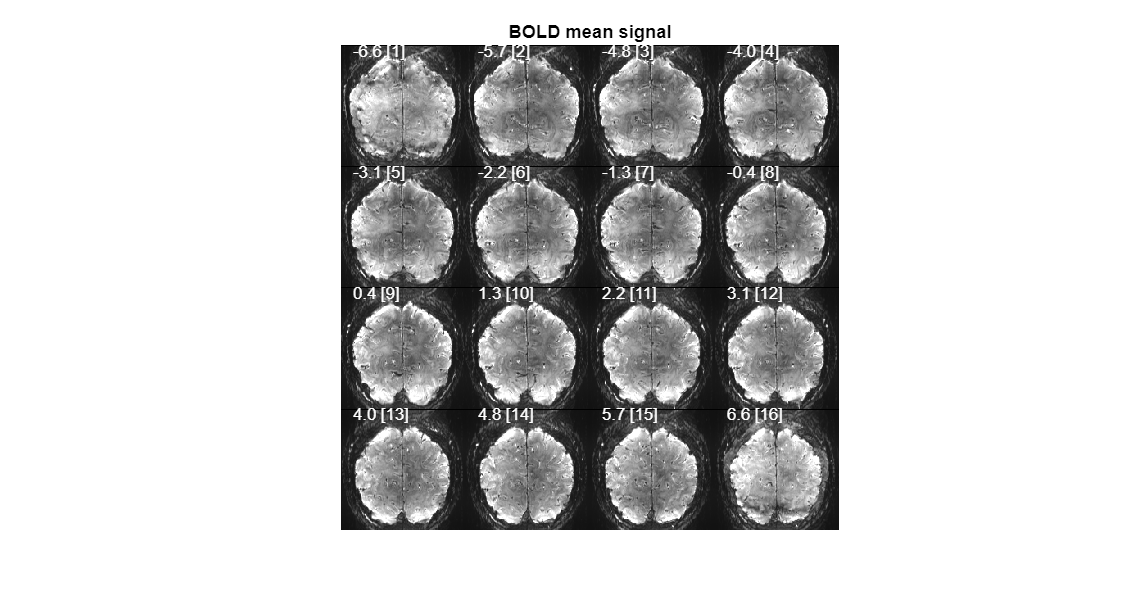

clc;
clear;
close all;
% Add SPM and uniQC to the path (Don't need to include this)

addpath('.\spm12'); % only add th top folder of SPM to the matlab path
addpath(genpath('.\tapas-master\UniQC\code')); % include subfolder as well for uniQC
dataPath = '.\ds004539'; % this needs to be adapted
subjectFolder = 'sub-14\ses-001\func'; % change to a different subject
SAVE = 'run-001';
run1 = MrImage(fullfile(dataPath, subjectFolder, 'sub-14_ses-001_task-blockStim_run-001_cbv.nii.gz'));

% Split data in BOLD and Nulled
% Blood oxygenation dependent (BOLD) signal image
% Start from 3 and 4 for BOLD and NULL respectively because  valid data starts from the third stimulus for BOLD
%  and the forth stimulus for NULL.
nVolumes = run1.dimInfo.nSamples(4);
BOLD = run1.select('t', 3:2:nVolumes-2);
NULL = run1.select('t', 4:2:nVolumes-2);
% Plot
%BOLD.plot('rotate90', 1); % Plot BOLD images
BOLD.mean.plot('rotate90', 1);% Plot mean BOLD image
title('BOLD mean signal');

## 1.2 Initial motion_correction

Realignment:  Produce the realigned MrImage object, estimated realignment parameters of BOLD and NULL.

[rBOLD, rp_BOLD] = BOLD.realign(); % the realigned MrImage object/image, estimated realignment parameters of BOLD



------------------------------------------------------------------------
01-Nov-2023 15:25:31 - Running job #1
------------------------------------------------------------------------
01-Nov-2023 15:25:31 - Running 'Realign: Estimate & Reslice'

SPM12: spm_realign (v7141)                         15:25:31 - 01/11/2023
Completed                               :          15:26:35 - 01/11/2023

SPM12: spm_reslice (v7141)                         15:26:35 - 01/11/2023
Completed                               :          15:28:49 - 01/11/2023
01-Nov-2023 15:28:49 - Done    'Realign: Estimate & Reslice'
01-Nov-2023 15:28:49 - Done



[rNULL, rp_NULL] = NULL.realign(); % the realigned MrImage object/image, estimated realignment parameters of NULL



------------------------------------------------------------------------
01-Nov-2023 15:29:04 - Running job #1
------------------------------------------------------------------------
01-Nov-2023 15:29:04 - Running 'Realign: Estimate & Reslice'

SPM12: spm_realign (v7141)                         15:29:04 - 01/11/2023
Completed                               :          15:30:14 - 01/11/2023

SPM12: spm_reslice (v7141)                         15:30:14 - 01/11/2023
Completed                               :          15:32:31 - 01/11/2023
01-Nov-2023 15:32:31 - Done    'Realign: Estimate & Reslice'
01-Nov-2023 15:32:31 - Done



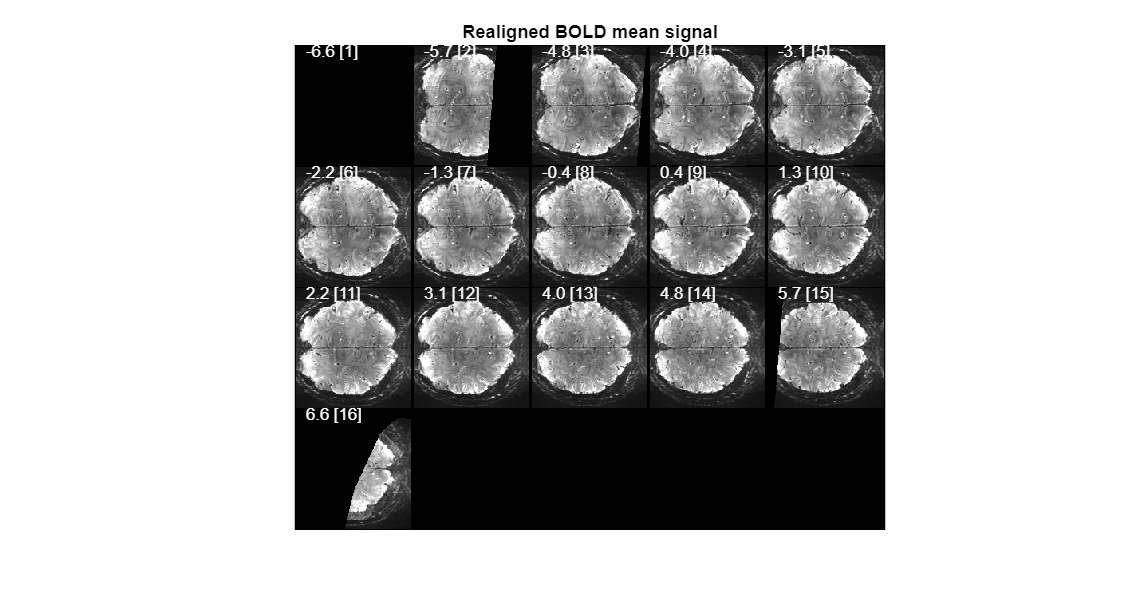


% Plot the result
figure;
rBOLD.mean.plot('rotat90', 1); 
title('Realigned BOLD mean signal');

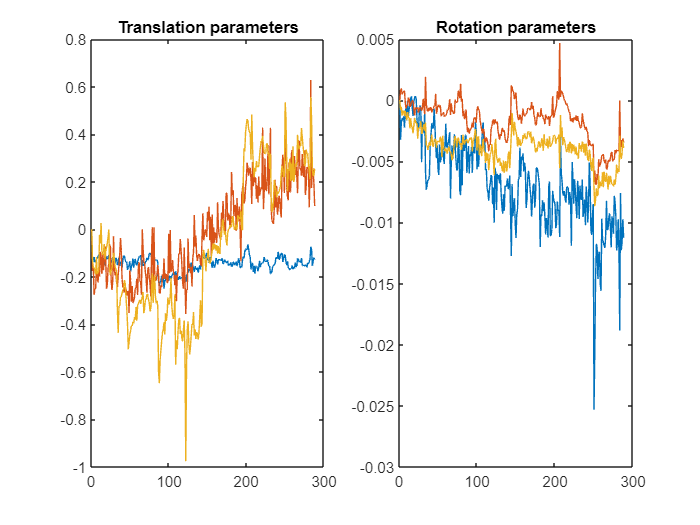


figure;
subplot(1,2,1); plot(rp_BOLD(:,1:3)); title('Translation parameters'); % the amount of displacement of the brain along the left right(x), anterior_posterior (y) 
% and superior -inferior (z) direction
subplot(1,2,2); plot(rp_BOLD(:,4:6)); title('Rotation parameters');% the amount of rotation of the brain along the left right(roll), anterior_posterior (pitch) 

% and superior -inferior (yaw) axes

## 1.3 Compute T1-like image

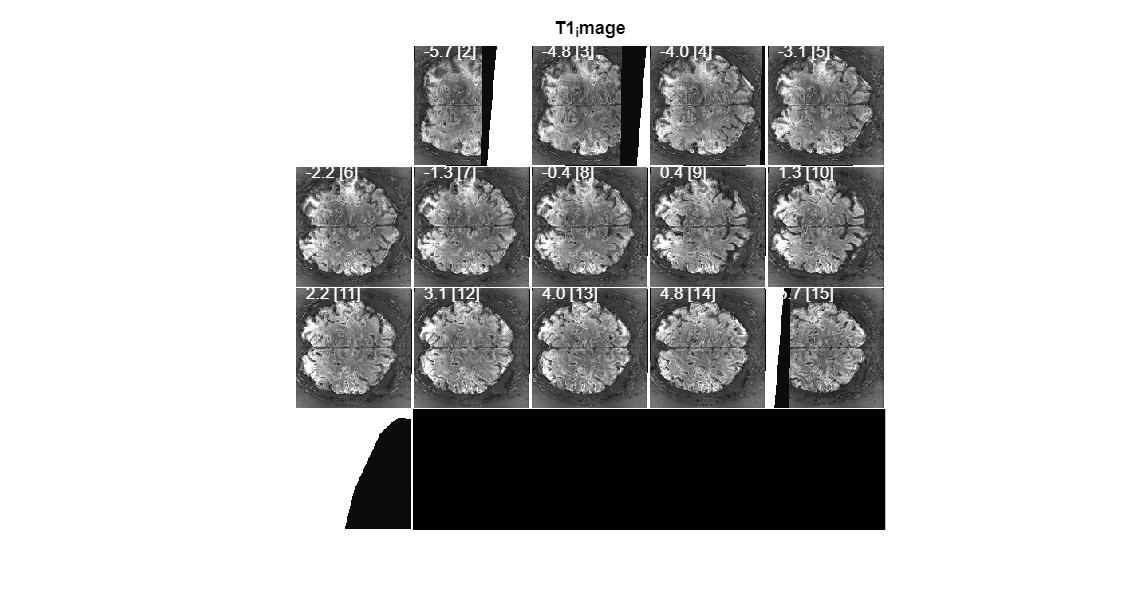

nVolumes = rBOLD.dimInfo.nSamples('t');  % extract the time dimension, which is the fourth dimension of realigned BOLD data.
total_data = rBOLD.copyobj;  % copy raligned BOLD data
 % Place the nulled data at the end of the rBOLD data to obtain complete data of both rBOLD and rNULL data
 % So, this will double time dimension 
total_data.data(:,:,:, nVolumes+1:nVolumes*2) = rNULL.data; % size of data: 152   148    16   576                                           
% Calculate the standard deviation and mean of the four-dimensional image total_data, calculate mean/std, and take the reciprocal
% MrImage holding voxel-wise coefficient of variation image (coeff_var), i.e. 1./snr 
T1_image = total_data.compute_coeff_var.^-1;    
% Correct T1 values
T1_image.data(isnan(T1_image.data)) = 0;% Not a number = NAN to be 0
T1_image.data(isinf(T1_image.data)) = 26;% Infinite number to be 26
T1_image.plot('displayRange', [0 20]);
title('T1_image');

## 1.4 Up sample the data with a factor of 2

% Up sample the realigned images : rBOLD and rNULL
rBOLD_initial = rBOLD.copyobj;
rNULL_initial = rNULL.copyobj;

scanning_number = max(size(rBOLD_initial.data,4),size(rNULL_initial.data,4)); % 288
% Upsample by factor of 2 by updating the new time samples/ scanning number in realigned images
pre_time_index = 1:scanning_number;
ups_time_index = 1:0.5:scanning_number; % Upsample by factor of 2

% Initialize the upsampling data for upsampling data
rBOLD_upsampling = zeros(size(rBOLD_initial.data,1), ...
                  size(rBOLD_initial.data,2), ...
                  size(rBOLD_initial.data,3), scanning_number*2-1);
rNULL_upsampling= zeros(size(rBOLD_initial.data,1), ...
                  size(rBOLD_initial.data,2), ...
                  size(rBOLD_initial.data,3), scanning_number*2-1);

% Time interpolation for 3D data of rBOLD and rNULL images/realigned images

for x = 1:size(rBOLD_initial.data,1)
    for y = 1:size(rBOLD_initial.data,2)
        for z = 1:size(rBOLD_initial.data,3)
            rBOLD_upsampling(x,y,z,:) = interp1( pre_time_index, squeeze(rBOLD_initial.data(x,y,z,:)), ...
                ups_time_index, 'linear');
            rNULL_upsampling(x,y,z,:) = interp1( pre_time_index, squeeze(rNULL_initial.data(x,y,z,:)), ...
                ups_time_index, 'linear'); %(576)*1 
        end
    end
end


% Upsample by factor of 2 by updating the new time samples/ scanning number in realignment parameters of BOLD and NULL

t_length = 1:size(rp_BOLD, 1);
t_upsampling = 1:0.5:size(rp_BOLD, 1);

% Initialize the upsampling data for upsampling data

rp_BOLD_upsampling = zeros(length(t_upsampling), size(rp_BOLD, 2));
rp_NULL_upsampling= zeros(length(t_upsampling), size(rp_NULL, 2));

% Time/Scanning interpolation for the 6 parameters of rp_BOLD and rp_NULL/ estimated realignment parameters of BOLD and NULL

for i = 1:size(rp_BOLD, 2)
    rp_BOLD_upsampling(:, i) = interp1(t_length, rp_BOLD(:, i), t_upsampling, 'linear');
    rp_NULL_upsampling(:, i) = interp1(t_length, rp_NULL(:, i), t_upsampling, 'linear');
end

## 1.5 Save the result

Save the data of BOLD and NULL  images/ parameters after upsampling 

% Save realigned BOLD images after upsampling

rBOLD_upsampling_img = MrImage(rBOLD_upsampling);
rBOLD_upsampling_img.parameters.save.path = fullfile(dataPath, subjectFolder, SAVE, 'BOLD');
rBOLD_upsampling_img.parameters.save.fileName = 'rBOLD_upsampling.nii';
rBOLD_upsampling_img.save();

%Save realignment BOLD parameters after upsampling

rp_BOLD_filename = fullfile(dataPath, subjectFolder, SAVE, 'rp_BOLD_upsampling.txt');
fileID = fopen(rp_BOLD_filename,'w');
fprintf(fileID,'%6.4f %6.4f %6.4f %6.4f %6.4f %6.4f\n', rp_BOLD_upsampling'); fclose(fileID);

%  Save realigned NULL images after upsampling

rNULL_upsampling_img = MrImage(rNULL_upsampling);
rNULL_upsampling_img.parameters.save.path = fullfile(dataPath, subjectFolder, SAVE, 'NULL');
rNULL_upsampling_img .parameters.save.fileName = 'rNULL_upsampling.nii';
rNULL_upsampling_img.save();

% Save realignment NULL parameters after upsampling

rp_NULL_filename = fullfile(dataPath, subjectFolder, SAVE, 'rp_NULL_upsampling.txt');
fileID = fopen(rp_NULL_filename,'w');
fprintf(fileID,'%6.4f %6.4f %6.4f %6.4f %6.4f %6.4f\n', rp_NULL_upsampling'); fclose(fileID);


## 1.6 BOLD-correction

% Duplicate the first nulled timepoint to temporally match the nulled and BOLD time series
% Select the first null and duplicate its time index number

first_NULL= rNULL_upsampling(:, :, :, 1);

% Insert the first slice back to time dimension as size(rNULL_upsampling)=  152   148    16   575
rNULL_upsampling_updated = cat(4, first_NULL, rNULL_upsampling); % size(NULL_upsampling_updated)=  152   148    16   576

% VASO = NULL/BOLD

VASO = rNULL_upsampling_updated (:, :, :, 1:(scanning_number*2-1)) ./ rBOLD_upsampling;%(:, :, :, 1:(scanning_number*2));
VASO_img = MrImage(VASO);
VASO_img.parameters.save.path = fullfile(dataPath, subjectFolder, SAVE, 'VASO');
VASO_img.parameters.save.fileName = 'VASO.nii';
VASO_img.save();

% Plot VASO
VASO_img.plot();
title('VASO image');

%  computed standard measures for
% quality control (tSNR, skew, and kurtosis) 
%rBOLD_upsampling.snr.plot;
% VASO.snr.plot;

**2 GLM  General linear model**

**2.1 Estimate activation maps from SPM BOLD**

% BOLD
contrast = 'BOLD';
contrast = 'BOLD';
load('glm_batch_spm12.mat') % Load data from spm12 wih 3 properties
matlabbatch{1}.spm.stats.fmri_spec.dir = {fullfile(dataPath, subjectFolder, SAVE, contrast)};
matlabbatch{1}.spm.stats.fmri_spec.sess.scans = ...
cellstr(spm_select('ExtFPList', fullfile(dataPath, subjectFolder, SAVE, contrast), 'rBOLD_upsampling.nii', inf));
matlabbatch{1}.spm.stats.fmri_spec.sess.multi_reg = {rp_BOLD_filename};
spm_jobman('run', matlabbatch);% interactive



------------------------------------------------------------------------
01-Nov-2023 15:34:53 - Running job #1
------------------------------------------------------------------------
01-Nov-2023 15:34:53 - Running 'fMRI model specification'
SPM12: spm_fMRI_design (v7739)                     15:34:58 - 01/11/2023
Saving fMRI design                      :               ...SPM.mat saved

SPM12: spm_fmri_spm_ui (v7738)                     15:34:58 - 01/11/2023
Mapping files                           :                        ...done
Calculating globals                     :                        ...done
Saving SPM configuration                :               ...SPM.mat saved
Saving SPM configuration                :               ...SPM.mat saved
Completed                               :          15:35:11 - 01/11/2023
01-Nov-2023 15:35:11 - Do

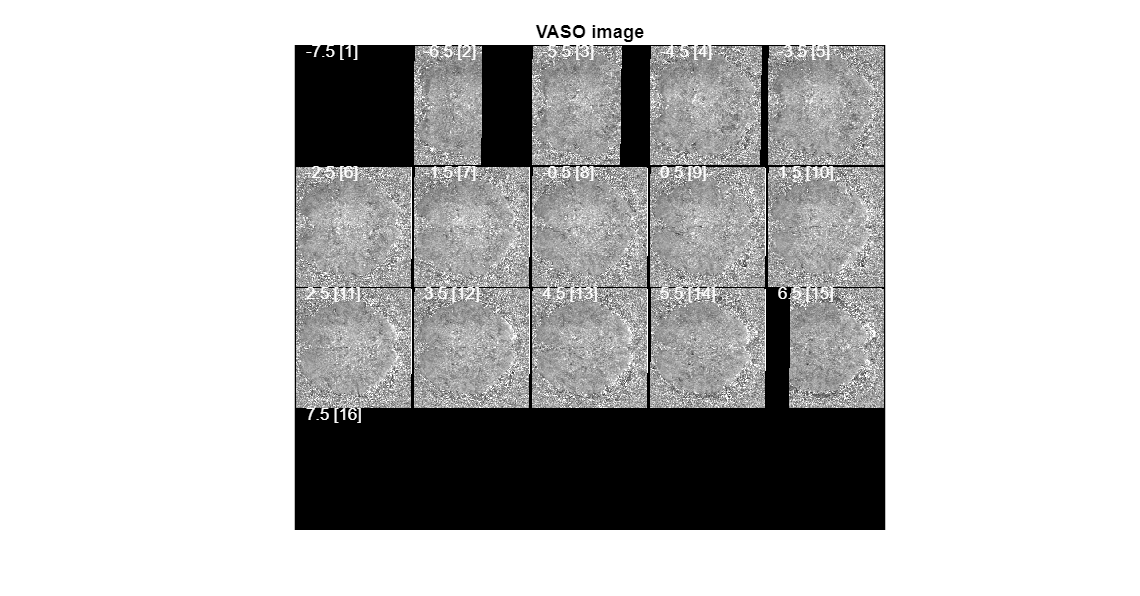

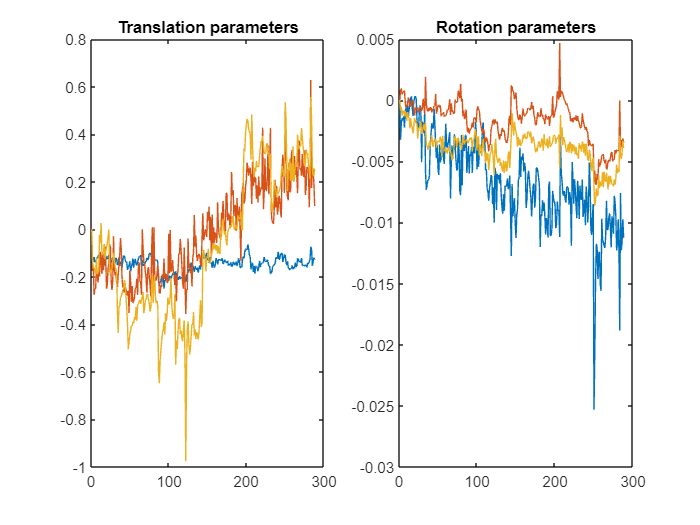



------------------------------------------------------------------------
01-Nov-2023 15:36:01 - Running job #1
------------------------------------------------------------------------
01-Nov-2023 15:36:02 - Running 'fMRI model specification'
SPM12: spm_fMRI_design (v7739)                     15:36:07 - 01/11/2023
Saving fMRI design                      :               ...SPM.mat saved

SPM12: spm_fmri_spm_ui (v7738)                     15:36:07 - 01/11/2023
Mapping files                           :                        ...done
Calculating globals                     :                        ...done
Saving SPM configuration                :               ...SPM.mat saved
Saving SPM configuration                :               ...SPM.mat saved
Completed                               :          15:36:20 - 01/11/2023
01-Nov-2023 15:36:20 - Do

	Saving SPM.mat                  :               ...SPM.mat saved
Completed                               :          15:36:58 - 01/11/2023
01-Nov-2023 15:36:58 - Done    'Contrast Manager'
01-Nov-2023 15:36:58 - Done




% VASO
contrast = 'VASO';
load('glm_batch_spm12.mat') % Load batch created from SPM12
matlabbatch{1}.spm.stats.fmri_spec.dir = {fullfile(dataPath, subjectFolder, SAVE, contrast)};
matlabbatch{1}.spm.stats.fmri_spec.sess.scans = ...
cellstr(spm_select('ExtFPList', fullfile(dataPath, subjectFolder, SAVE, contrast), 'VASO.nii', inf));
matlabbatch{1}.spm.stats.fmri_spec.sess.multi_reg = {rp_NULL_filename};
spm_jobman('run', matlabbatch);

## 2.2 Plot activation maps 

**BOLD**

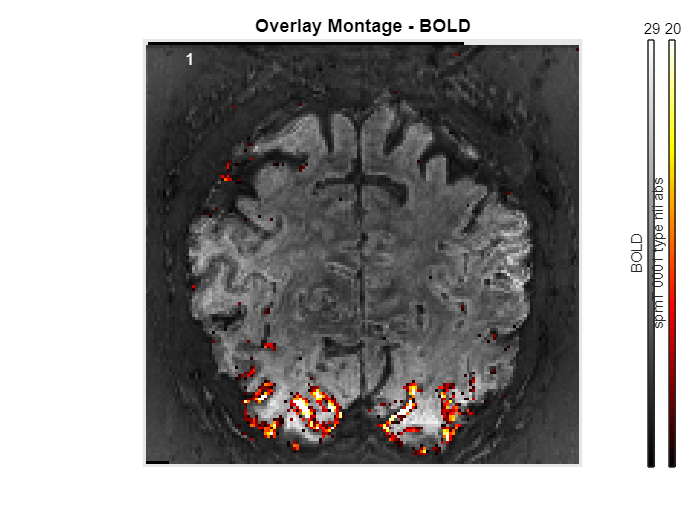

t_map_BOLD = MrImage(fullfile(dataPath, subjectFolder, SAVE, 'BOLD','spmT_0001.nii')); % size 152   148    16
image_number = 10; % Select the slice to be presented
underlay_image = T1_image; %% size 152   148    16
% Plot overlay BOLD
figure;
underlay_image.name = 'BOLD';
underlay_image.select('z', image_number).plot_overlays(...
    t_map_BOLD.select('z', image_number), ...
    'rotate90',         1, ...
    'overlayMode',      'map', ...
    'overlayThreshold', [6 20], ...
    'overlayAlpha',     1, ...
    'overlayColorMaps', {'hot'});

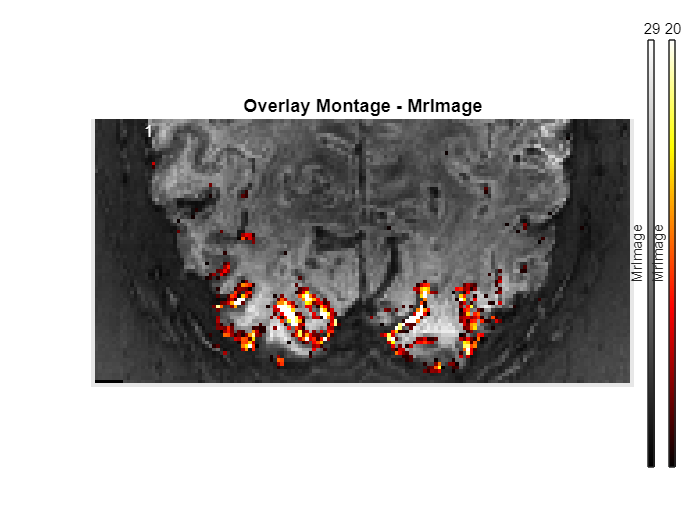

% Segmentation
% Plot overlay BOLD with slected the interest of regions
figure;
underlay_image.name = 'BOLD';
y_segment = 75;
t_map_BOLD_Ysegment = MrImage(t_map_BOLD.data(:,1:y_segment,:)); % 152    55    16
underlay_image_Ysegment = MrImage(underlay_image.data(:, 1:y_segment,:));
underlay_image_Ysegment.select('z', image_number).plot_overlays(...
    t_map_BOLD_Ysegment.select('z', image_number), ...
    'rotate90',         1, ...
    'overlayMode',      'map', ...
    'overlayThreshold', [6 20], ...
    'overlayAlpha',     1, ...
    'overlayColorMaps', {'hot'});

## VASO

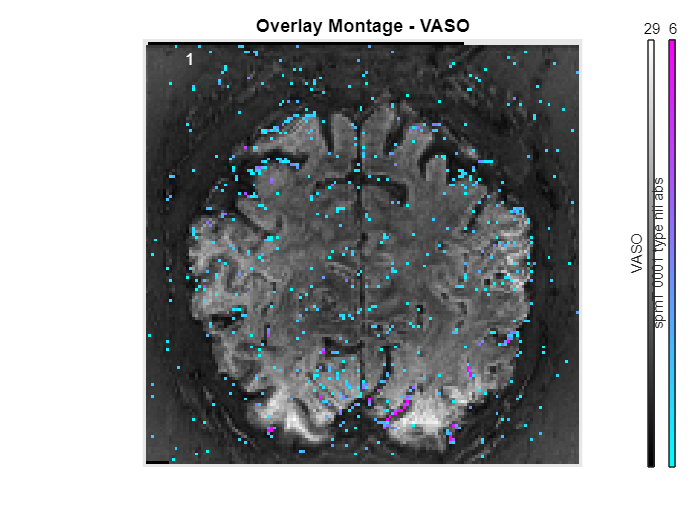

t_map_VASO = MrImage(fullfile(dataPath, subjectFolder, SAVE,'VASO', 'spmT_0001.nii')); % size 152   148    16
t_map_VASO_created = t_map_VASO.copyobj;
image_number =10;
y_segment = 65;
% Prepare the threshold for plotting
edge_min = 2.5;
edge_max =6;
smallest_obj = 2;
% Copy data from t_map_VASO
t_map_VASO_img_selected = t_map_VASO_created.data(:,:,image_number); % size 152   148
% Keep the pixel value in the range/limit.
t_map_VASO_img_limited = t_map_VASO_img_selected >= edge_min & t_map_VASO_img_selected <= edge_max;
% Use bwareaopen Delete small object/noise
t_map_VASO_img_objdeleted = bwareaopen(t_map_VASO_img_limited, smallest_obj); 

% Multiply the cleaned binary image by the original image 
t_map_VASO_img_objdeleted = t_map_VASO_img_objdeleted .* t_map_VASO_img_selected;

%t_map_VASO_created.data(:,:,image_number) = t_map_VASO_img_objdeleted;

% underlay_image = T1_image;
underlay_image.name = 'VASO';
% Draw the overlay graph
underlay_image.select('z', image_number).plot_overlays(...
    t_map_VASO_created.select('z', image_number), ...
    'rotate90',         1, ...
    'overlayMode',      'map', ...
    'overlayThreshold', [edge_min edge_max], ...
    'overlayAlpha',     1, ...
    'overlayColorMaps', {'cool'});

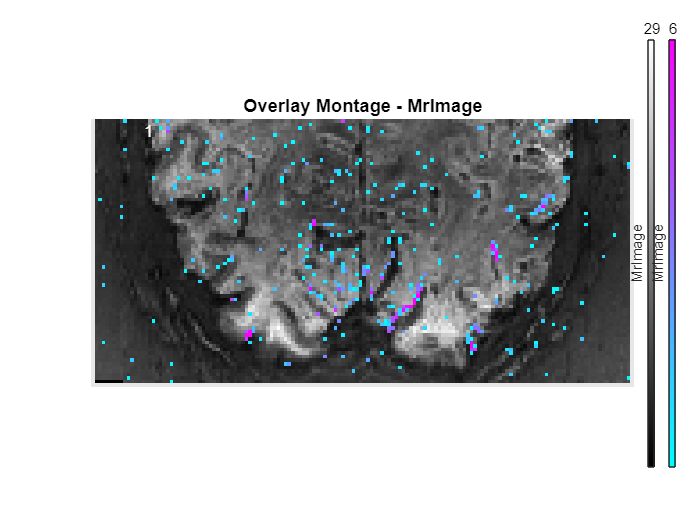

% segmentation
% seg_y = 60;
t_map_VASO_Ysegment = MrImage(t_map_VASO_created.data(:,1:y_segment,:));
underlay_image_Ysegment.select('z', image_number).plot_overlays(...
    t_map_VASO_Ysegment.select('z', image_number), ...
    'rotate90',         1, ...
    'overlayMode',      'map', ...
    'overlayThreshold', [edge_min edge_max], ...
    'overlayAlpha',     1, ...
    'overlayColorMaps', {'cool'});

## 3. Estimate percent signal change

BOLD

%r_brainmask = MrImage(char(fullfile(dataPath, subjectFolder, SAVE, 'BOLD', "mask.nii"))); % size 152   148    16
threshold1 = 6;
%activation_mask_BOLD = binarize(t_map_BOLD.*r_brainmask, threshold1);
activation_mask_BOLD = binarize(t_map_BOLD, threshold1);
rBOLD_upsampling_img.extract_rois(activation_mask_BOLD);
rBOLD_upsampling_img.compute_roi_stats();
BOLD_data = cell2mat(rBOLD_upsampling_img.rois{1}.data(:)); % 302876         575

% VASO

%r_brainmask = MrImage(char(fullfile(dataPath, subjectFolder, SAVE, 'VASO', "mask.nii"))); % size: 152   148    16
threshold2 =6;
%activation_mask_VASO = binarize(t_map_VASO.*r_brainmask, threshold2); % transforms image into binary image with pixels >= threshold set to 1
activation_mask_VASO = binarize(t_map_VASO, threshold2);
VASO_img.extract_rois(activation_mask_VASO);% Extracts data from this image for voxels within rois (regions of interest )given by mask images
VASO_data = cell2mat(VASO_img.rois{1}.data(:));% M = CELL2MAT(C) converts a multidimensional cell array with contents of
%   the same data type into a single matrix. 
% size(VASO_data) =674   575;

##  Average the voxel signal and plot the signal percentage change

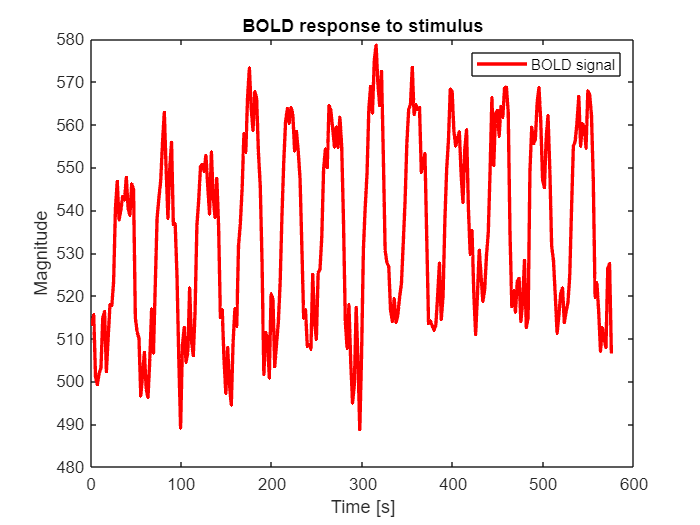


figure;
plot(mean(BOLD_data,1), 'r', 'LineWidth', 2);
legend('BOLD signal');
title('BOLD response to stimulus');
xlabel('Time [s]');
ylabel('Magnitude');

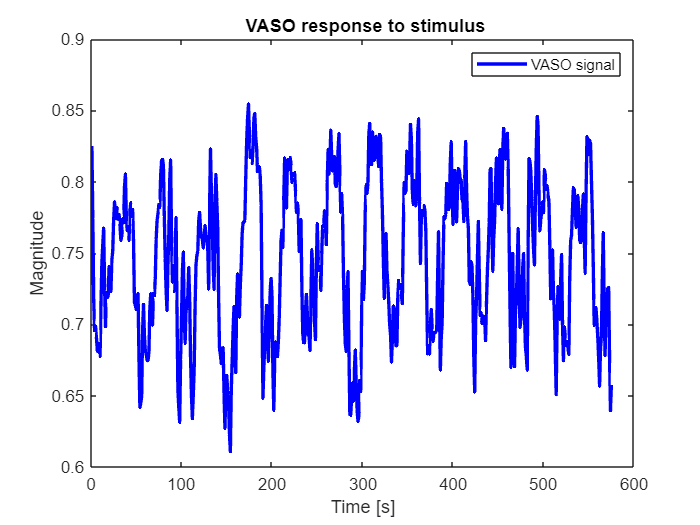

%ylim([285 300]);
figure;
plot(mean(VASO_data,1), 'b', 'LineWidth', 2);
legend('VASO signal');
title(' VASO response to stimulus');
xlabel('Time [s]');
ylabel('Magnitude');

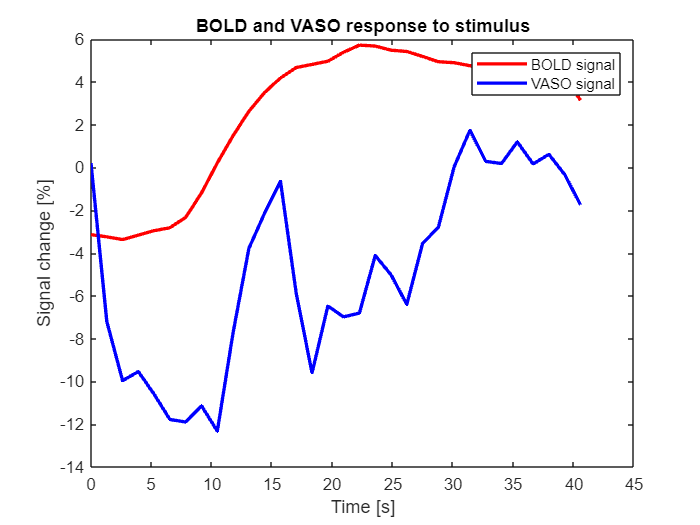

 % oneset = 27.383 87.383 147.383 207.383 267.383 327.383 387.383 447.383 507.383 567.383 627.383 687.383
oneset = 30-2.617:60:12*60;
time_sr = 750;%684.766+30;%720; % seconds
volume_interval = 1.3085;% seconds

BOLD_mean_signal = (mean(BOLD_data,1));
VASO_mean_signal = (mean(VASO_data,1));
 for i =1:12
% BOLD epoch with stimulation with 4 volumes before stimulus onset and 8 volumes after cessation
BOLD_index_start =ceil((oneset(i)/volume_interval)) - 4 ;% 4 volumes before stimulus onset 17
BOLD_index_end = BOLD_index_start + 8 + ceil(30/volume_interval);% and 8 volumes after cessation 48
BOLD_value  = BOLD_mean_signal(1,(BOLD_index_start:BOLD_index_end));

% VASO epoch with stimulation with 4 volumes before stimulus onset and 8 volumes after cessation
VASO_index_start = 2  ;% Manually select the starting index of VASO
VASO_index_end = VASO_index_start + 8 + ceil(30/volume_interval) ;% and 8 volumes after cessation 48
VASO_value = VASO_mean_signal(1,(VASO_index_start:VASO_index_end));

% REST index of the signal response with 30 s rest-periods in between stimulation blocks
%BOLD REST

REST_index_start = BOLD_index_end - 8  ; 
REST_index_end = REST_index_start+ ceil(30 /volume_interval); 
% Mean of BOLD rest
REST_value_mean1 = mean(BOLD_mean_signal(1,(REST_index_start:REST_index_end)));

%VASO REST
REST_index_start2 = VASO_index_end - 8  ;
REST_index_end2 = REST_index_start2+ ceil(30 /volume_interval); 
% Mean of VASO rest
REST_value_mean2 = mean(VASO_mean_signal(1,(REST_index_start2:REST_index_end2)));

% Store Percent of BOLD change of each block
percent_BOLD(i,:) = (BOLD_value - REST_value_mean1)*100/REST_value_mean1;
% Store Percent of VASO change  of each block
percent_VASO(i,:) = (VASO_value - REST_value_mean2)*100 /REST_value_mean2;
end
% Average epochs with stimulation with 4 volumes before stimulus onset and 8 volumes after cessation
mean_percent_BOLD = (mean(percent_BOLD,1));

% Average the signal response with 30 s rest-periods in between stimulation blocks
mean_percent_VASO = (mean(percent_VASO,1));
% Convert index values to  the time range of each epoch 
time_domain = ((BOLD_index_end - BOLD_index_start)*1.3085);% volume_interval = 1.3085 second
time = 0: (1.3085): time_domain; %volume_interval = 1.3085 second
figure;
plot(time,mean_percent_BOLD, 'r', 'LineWidth', 2);
hold on;
plot(time, mean_percent_VASO, 'b', 'LineWidth', 2);
legend('BOLD signal', 'VASO signal');
title('BOLD and VASO response to stimulus');
xlabel('Time [s]');
ylabel('Signal change [%]');

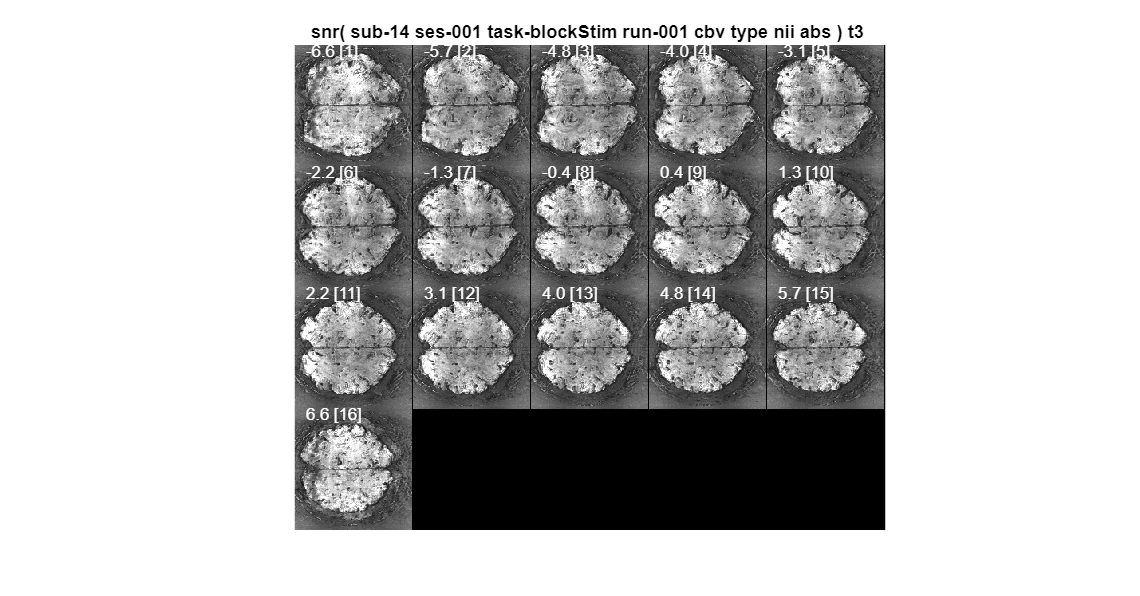

%  Compute standard measures for quality control (tSNR, skew, and kurtosis) 
%rBOLD_upsampling.snr.plot;
BOLD.snr.plot;

%VASO_image.snr.plot;